# Predicting Fuel Economy

Train regression models to predict fuel economy of vehicles.

#### Load and Prepare Data

carData = readtable("carData.csv");
carData = convertvars(carData,vartype("cellstr"),"categorical");

cvpt = cvpartition(carData.FuelEcon,"HoldOut",0.32);

carTrain = carData(training(cvpt),:);
carTest = carData(~training(cvpt),:);

## Linear Models

Plot fuel economy vs engine displacement.

clf
scatter(carData.EngDisp,carData.FuelEcon,".")

Fit a single-predictor linear model of fuel economy.

mdl = fitlm(carTrain.EngDisp,carTrain.FuelEcon);

Add model to the plot.

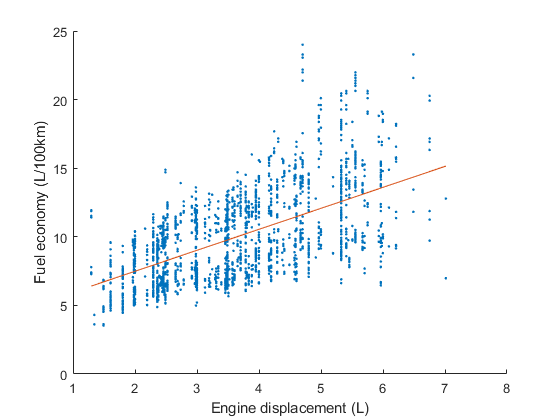

x = [min(carData.EngDisp);max(carData.EngDisp)];
y = predict(mdl,x);
hold on
plot(x,y)
hold off
xlabel("Engine displacement (L)")
ylabel("Fuel economy (L/100km)")

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest.EngDisp);

Plot predicted and actual responses vs. observation number.

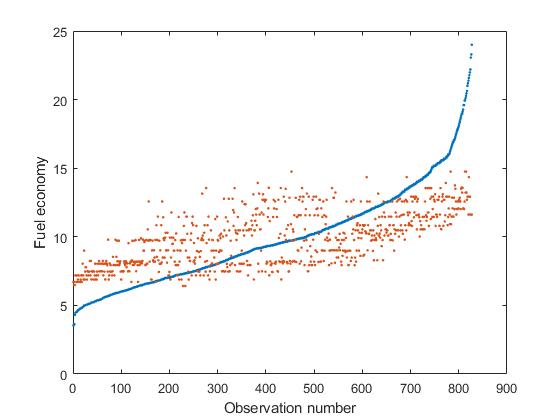

plot(carTest.FuelEcon,".")
hold on
plot(econpred,".")
hold off
xlabel("Observation number")
ylabel("Fuel economy")

Plot predicted and actual responses against each other.

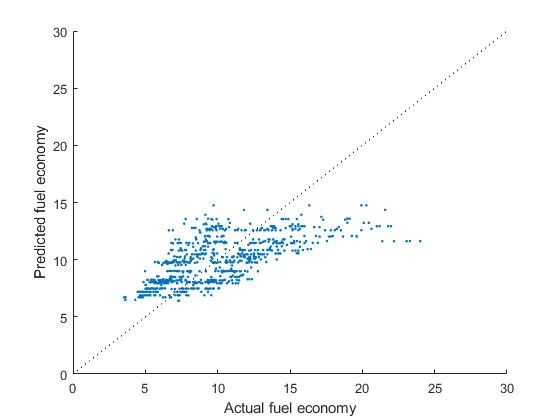

scatter(carTest.FuelEcon,econpred,".")
% add diagonal line
hold on
plot([0 30],[0 30],"k:")
hold off
xlabel("Actual fuel economy")
ylabel("Predicted fuel economy")

Plot distribution of errors.

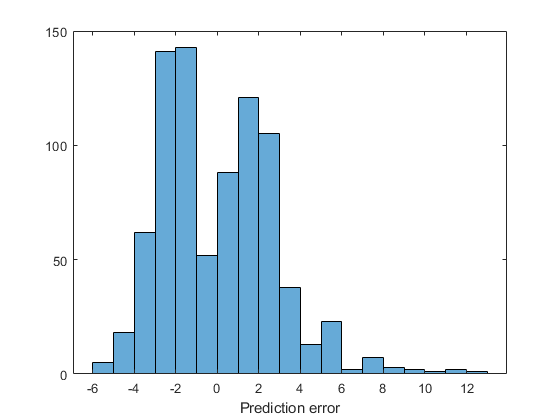

err = carTest.FuelEcon - econpred;
histogram(err)
xlabel("Prediction error")

MSE = mean(err.^2)

MSE = 7.5434

Plot distribution of percentage errors.

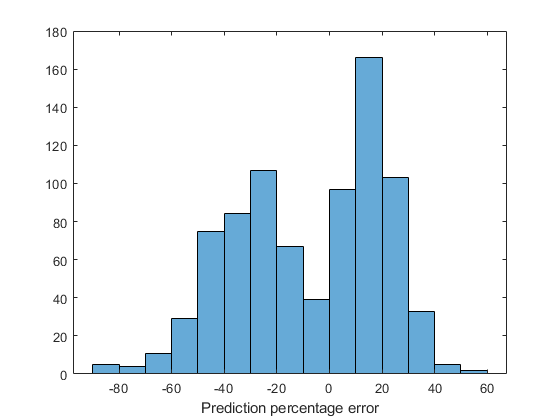

percerr = 100*err./carTest.FuelEcon;
histogram(percerr)
xlabel("Prediction percentage error")

MAPE = mean(abs(percerr))

MAPE = 24.4363

## Multivariate Linear Models

Fit a multivariate linear model of fuel economy.

mdl = fitlm(carTrain);

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

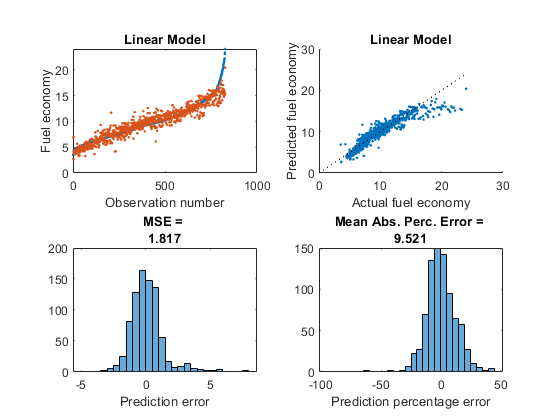

evaluatefit(carTest.FuelEcon,econpred,"Linear Model")

Fit and evaluate a multivariate linear model with robust fitting.

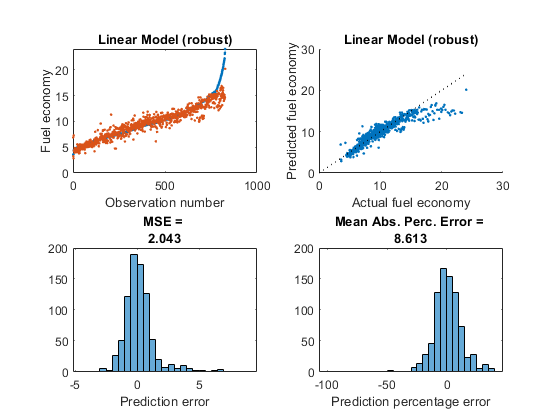

mdl = fitlm(carTrain,"RobustOpts","cauchy");
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Linear Model (robust)")

## Stepwise Fitting

Perform a stepwise linear fit of fuel economy.

mdl = stepwiselm(carTrain);

1. Adding City_Highway, FStat = 1231.2278, pValue = 6.7117696e-205
2. Adding EngDisp, FStat = 2952.7406, pValue = 0
3. Adding EngDisp:City_Highway, FStat = 227.4625, pValue = 2.005625e-48
4. Adding Weight, FStat = 257.6422, pValue = 3.330078e-54
5. Adding Transmission, FStat = 13.4668, pValue = 1.26677e-34
6. Adding Drive, FStat = 60.9396, pValue = 2.6394e-26
7. Adding Valves_Cyl, FStat = 61.2562, pValue = 8.64365e-15
8. Adding Comp, FStat = 62.836, pValue = 3.98526e-15
9. Adding EngDisp:Transmission, FStat = 6.8602, pValue = 3.1046e-12
10. Adding Transmission:Valves_Cyl, FStat = 9.9204, pValue = 2.5329e-16
11. Adding Drive:Valves_Cyl, FStat = 40.3078, pValue = 7.84208e-18
12. Adding FuelType, FStat = 60.5131, pValue = 1.2546e-14
13. Adding EngDisp:FuelType, FStat = 197.9218, pValue = 1.285022e-42
14. Adding Transmission:FuelType, FStat = 15.9628, pValue = 1.98793e-20
15. Adding Transmission:Weight, FStat = 6.0101, pValue = 2.1814e-12
16. Adding AC, FStat = 53.6907, pValue = 3.62244e-1

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

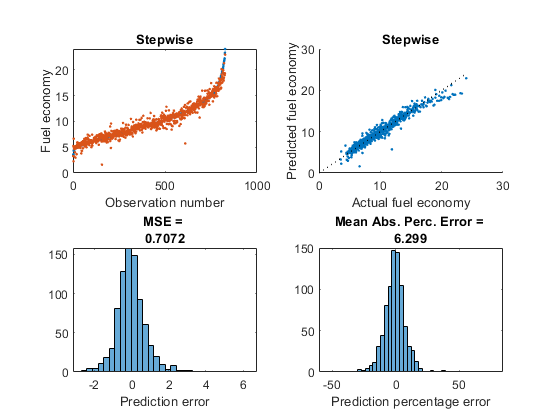

evaluatefit(carTest.FuelEcon,econpred,"Stepwise")

Change criterion and limit to linear models.

mdl = stepwiselm(carTrain,"Criterion","aic","Upper","linear");

1. Adding City_Highway, AIC = 8160.8691
2. Adding EngDisp, AIC = 6427.465
3. Adding Weight, AIC = 6219.5307
4. Adding Transmission, AIC = 6065.9098
5. Adding Drive, AIC = 5964.5861
6. Adding Valves_Cyl, AIC = 5913.6396
7. Adding Comp, AIC = 5868.5743
8. Adding FuelType, AIC = 5835.153
9. Adding Car_Truck, AIC = 5809.0289
10. Adding EVSpeedRatio, AIC = 5778.5294
11. Adding RatedHP, AIC = 5762.2568
12. Adding AC, AIC = 5737.6937
13. Adding AxleRatio, AIC = 5737.2433


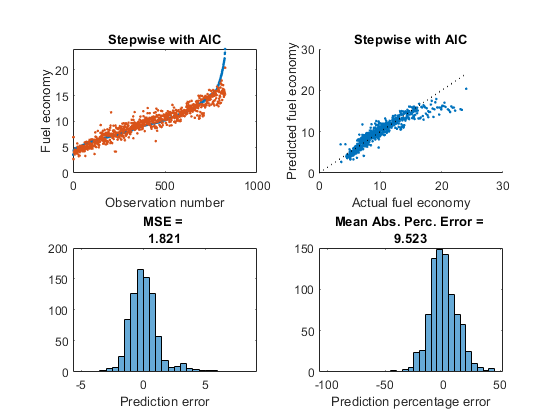

econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Stepwise with AIC")

## Regularized Linear Models

#### Prepare data

Extract response variable.

econTrain = carData.FuelEcon(training(cvpt));
econTest = carData.FuelEcon(~training(cvpt));

Make dummy variables with n-1 columns for categorical predictors with n categories.

minus1 = @(x) x(:,1:end-1);
T = splitvars(convertvars(carData(:,1:end-1),vartype("categorical"),@(x) minus1(dummyvar(x))));
XTrain = T{training(cvpt),:};
XTest = T{~training(cvpt),:};

Fit ridge regression model.

lambdaR = 0:30;
bR = ridge(econTrain,XTrain,lambdaR,0);

Calculate and plot MSE. Find smallest MSE.

econPredR = bR(1,:) + XTest*bR(2:end,:);
err = econPredR - econTest;
MSER = mean(err.^2);
[minMSER,idxR] = min(MSER)

minMSER = 1.8152

idxR = 5

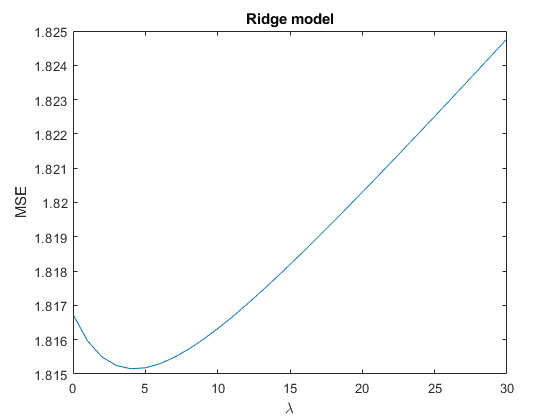


clf
plot(lambdaR,MSER)
xlabel("\lambda")
ylabel("MSE")
title("Ridge model")

Compare predicted and actual responses.

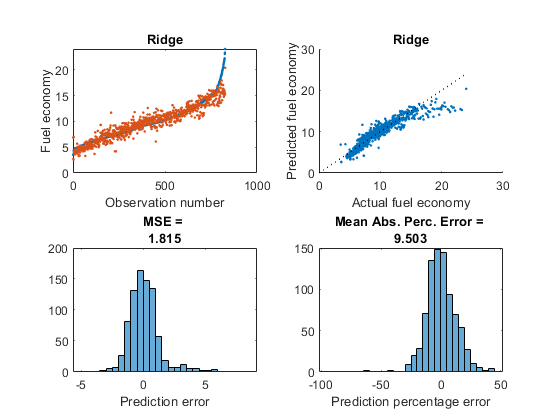

econpred = econPredR(:,idxR);
evaluatefit(carTest.FuelEcon,econpred,"Ridge")

Fit lasso model.

lambdaL = lambdaR/length(econTrain);
[bL,fitInfo] = lasso(XTrain,econTrain,"Lambda",lambdaL);

Calculate and plot MSE. Find smallest MSE.

econPredL = fitInfo.Intercept + XTest*bL;
err = econPredL - econTest;
MSEL = mean(err.^2);
[minMSEL,idxL] = min(MSEL)

minMSEL = 1.8152

idxL = 2

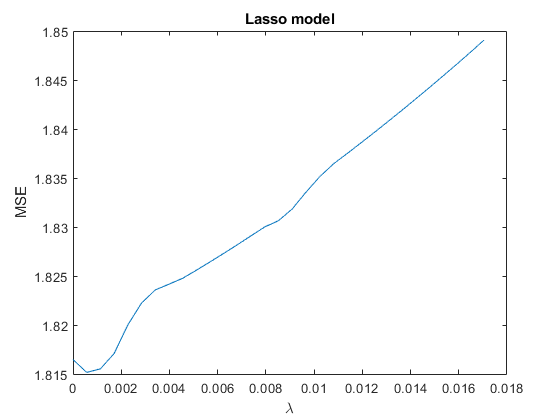


clf
plot(lambdaL,MSEL)
xlabel("\lambda")
ylabel("MSE")
title("Lasso model")

Compare predicted and actual responses.

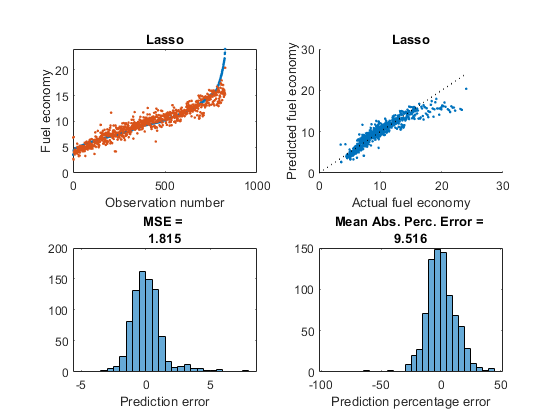

econpred = econPredL(:,idxL);
evaluatefit(carTest.FuelEcon,econpred,"Lasso")

## SVMs

Fit an SVM regression model of fuel economy.

mdl = fitrsvm(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses.

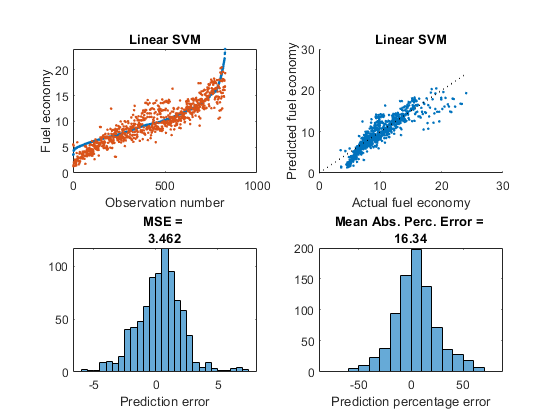

evaluatefit(carTest.FuelEcon,econpred,"Linear SVM")

Standardize variables.

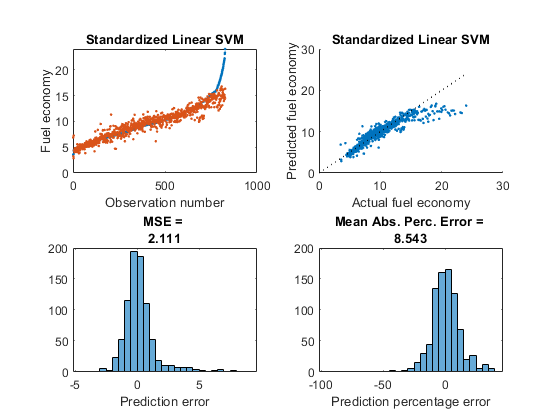

mdl = fitrsvm(carTrain,"FuelEcon","Standardize",true);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Standardized Linear SVM")

Try a different kernel.

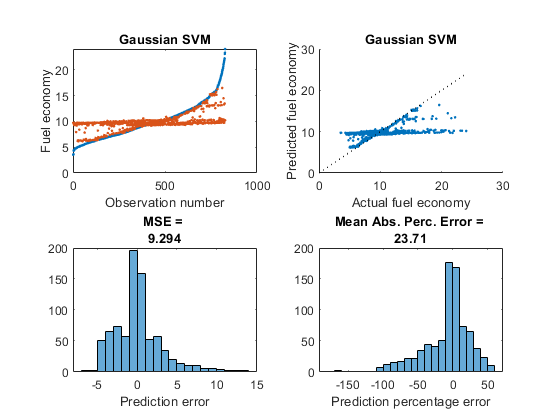

mdl = fitrsvm(carTrain,"FuelEcon","KernelFunction","gaussian");
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Gaussian SVM")

## Decision Trees

Fit a decision tree regression model of fuel economy.

mdl = fitrtree(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

econpred = predict(mdl,carTest);

Compare predicted and actual responses

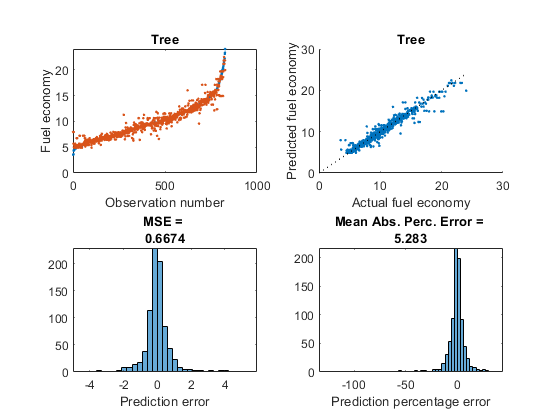

evaluatefit(carTest.FuelEcon,econpred,"Tree")

Prune the tree.

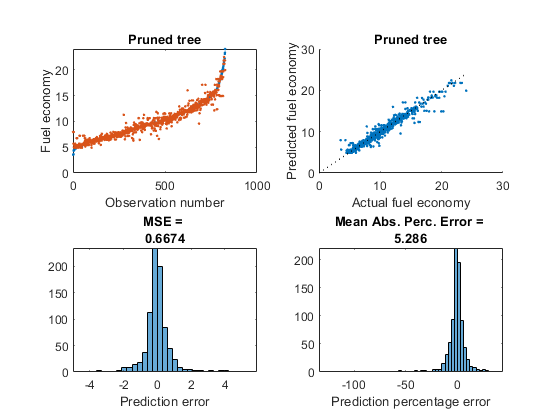

mdl = prune(mdl,"Level",10);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Pruned tree")

Set minimum leaf size.

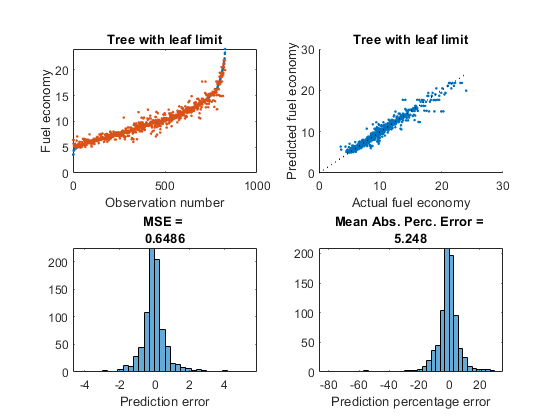

mdl = fitrtree(carTrain,"FuelEcon","MinLeafSize",5);
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"Tree with leaf limit")

## Gaussian Process Regression

Fit a Gaussian process model of fuel economy.

mdl = fitrgp(carTrain,"FuelEcon");

Predict fuel economy at test predictor values.

[econpred,~,epint] = predict(mdl,carTest);

Compare predicted and actual responses.

evaluatefit(carTest.FuelEcon,econpred,"GPR")

Add intervals to predictions.

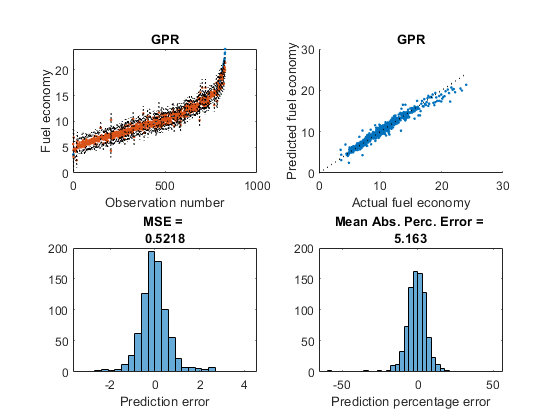

subplot(2,2,1)
hold on
plot(epint,"k:")
hold off

Try a different kernel.

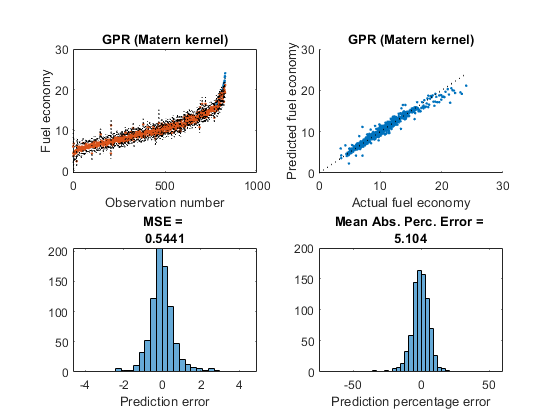

mdl = fitrgp(carTrain,"FuelEcon","KernelFunction","matern52");
[econpred,~,epint] = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,"GPR (Matern kernel)")
subplot(2,2,1)
hold on
plot(epint,"k:")
hold off

**Local function:** `evaluatefit`

function evaluatefit(y,ypred,name)
figure
% Plot against observation number
subplot(2,2,1)
plot(y,".")
hold on
plot(ypred,".")
title(name)
xlabel("Observation number")
ylabel("Fuel economy")

% Plot predicted and actual against each other
subplot(2,2,2)
scatter(y,ypred,".")
% Add 45-degree line
xl = xlim;
hold on
plot(xl,xl,"k:")
title(name)
xlabel("Actual fuel economy")
ylabel("Predicted fuel economy")

% Distribution of errors
subplot(2,2,3)
err = y - ypred;
MSE = mean(err.^2,"omitnan");
histogram(err)
title(["MSE = ",num2str(MSE,4)])
xlabel("Prediction error")

% Distribution of percentage errors
subplot(2,2,4)
err = 100*err./y;
MAPE = mean(abs(err),"omitnan");
histogram(err)
title(["Mean Abs. Perc. Error = ",num2str(MAPE,4)])
xlabel("Prediction percentage error")
end